# Actividad #8

#### Fecha: 22/06/2024

#### Objetivos:

- Cargar automaticamente datos desde la arpeta "data"

- usar las funciones en la carpeta "src"

#### Nombre:

- sunombre

#### Repository:

- [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

#### Librarys:

- [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

## Paso 1: Limpiar variables y linea de comandos

clear % Para borrar el workspace y liberar memoria RAM
clc  % Limpiar el command window

## Paso 2.- Configuración de carpeta ./src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

## **Paso 3- Configuranción de carpeta de ./data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');

## **Paso 4- Buscar los nombres de todos los archivos dentro de la carpeta ./data**

%Nombre de la carpeta donde estan los archvios csv
filenames=FindCSV(datapath);

## Paso 3: Cargar los datos en formato CSV

Es importante que el archivo csv se encuentre en la misma carpeta que el main

AllData=[];
for i=1:1:length(filenames)
    %Leer un archivo csv y lo carga como una tabla
    Dataset=readtable("./data/Data3.csv");
    %Convertir la tabla en una matrix de valores
    Dataset=table2array(Dataset);
    AllData=[AllData;Dataset];
end

maxfilas=length(AllData);%Maximo numero de filas
%Estos son los nombres de las variables
vname=["Corriente","Voltaje","variable3","variable4","variable5"];

## Paso 3: Graficar el dataset

Seleccionar el numero de variables a mostrar


nvar=1;
nfilas=100;

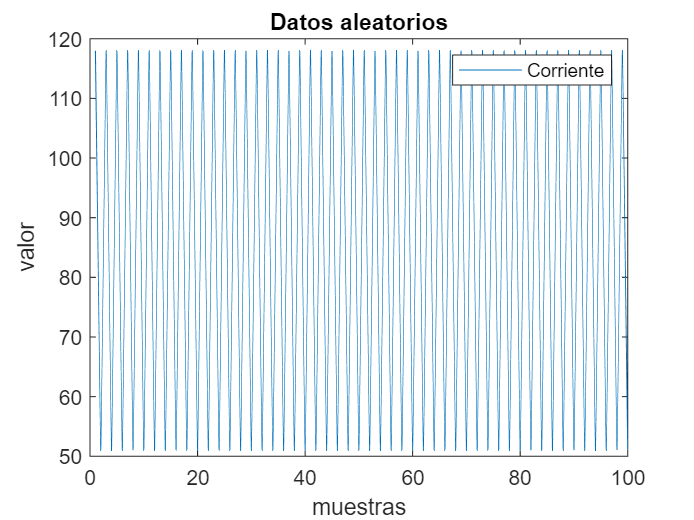

figure %no sobrescribe la anterior grafica
plot(AllData(1:nfilas,1:nvar));%
title("Datos aleatorios");
xlabel("muestras");
ylabel("valor");
legend(vname(1:nvar))